# Inverse Kinematics

In the previous section, we saw how the Forward Kinematics of a Robot can be modelled using the  DH Parameters, such that we can supply the joint angles and find the position of every joint and end-effector on the Robot. Next, we'll see how to calculate the **Inverse Kinematics of a Robot**, i.e. to find the specific joint angles to get the robot's end effector to a certain place. 

Inverse kinematics aims to obtain the robot's joint angles by utilizing the position and orientation of a robot's end-effector, thus defining the robot's motion path. Because of this, the robot's motion is centered around the end-effector. This means each joint will move with respect to the location of the end-effector. Each joint rotates together, creating line trajectories for the robot. For example, pictured below is a 3-joint robot. Moving the end-effector to a given location will rotate joints 1, 2, and 3 simultaneously, producing a line movement. This type of action more closely represents how we move our arms to complete a task. When you obtain the end-effector's final location, you can determine the joint angles that made it possible to achieve that location.

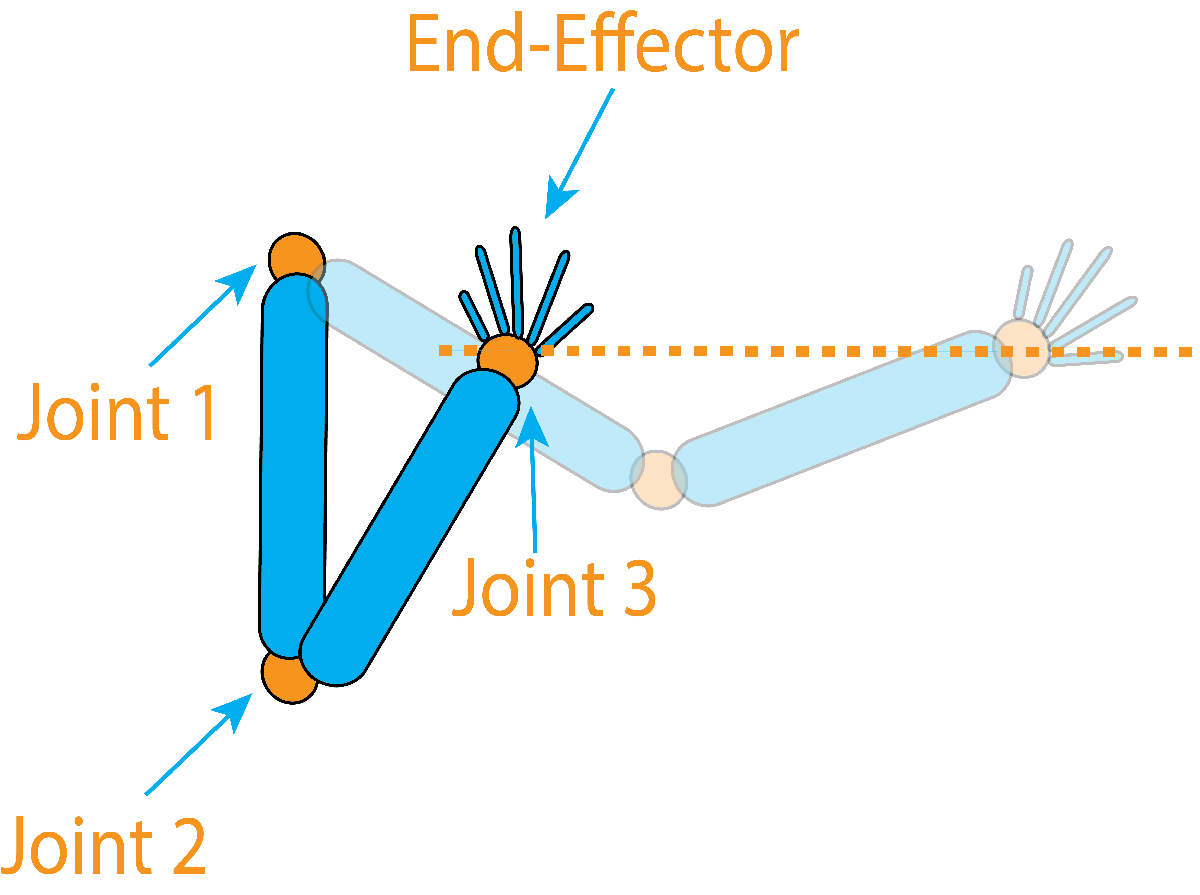

## The Challenge with Inverse Kinematics

Inverse kinematics is more challenging to work with than forward kinematics because there are usually multiple solutions (combinations of joint angles) that can achieve the desired end-effector target location; the manipulator in the image above is one example. In addition, you may have bounds and limits in which your manipulator can operate. That is, one joint may have a smaller range of operating angles than another and would need to be optimized simultaneously to achieve the end-effector's final position and orientation. A few classifications of robots define how good of an inverse kinematic solution you will have for a given target location. For instance, under-actuated robots may reach the target position but not the orientation of the end-effector. Meanwhile, fully actuated robots may have multiple ways to reach the target position and orientation. Then, there are redundant robots that can have an infinite number of solutions that achieve the target position and orientation. These types are shown in the following table:

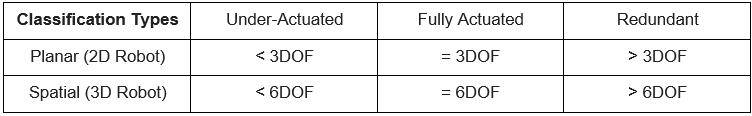

This problem becomes exceedingly more difficult as you increase the number of joints in the manipulator. Because of these challenges, mathematicians use two primary approaches to solve the inverse kinematics problem. Each approach has two specific methods to choose from:

- **Analytical Solutions** (Algebraic, Geometric) - Derived equations solving for joint angles, which are a function of the end-effector location

- **Approximate Solutions **(Jacobian Inverse, Cyclic Coordinate Descent) - Iterative method of numerically computing joint angles by moving closer to the end-effector location each iteration

It is important to understand when you should consider using one approach over the other:

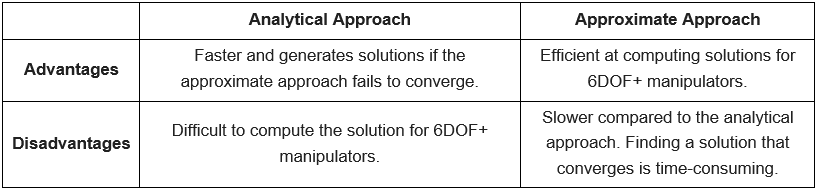

In this module, we will see an example of an Analytical solution to the Inverse Kinematics problem, as well as an overview of the Jacobian Inverse method. 

For the Jacobian Inverse, we will require the end location of the end-effector and the transformation matrices calculated from the forward kinematics. Recall that the transformation matrix comprises the rotation (3x3) and translation (3x1) matrices.

## 1. Analytical Solution for Inverse Kinematics for a 6 DOF Robot

Consider a typical 6 DoF Robot, similar to what we have been looking at.

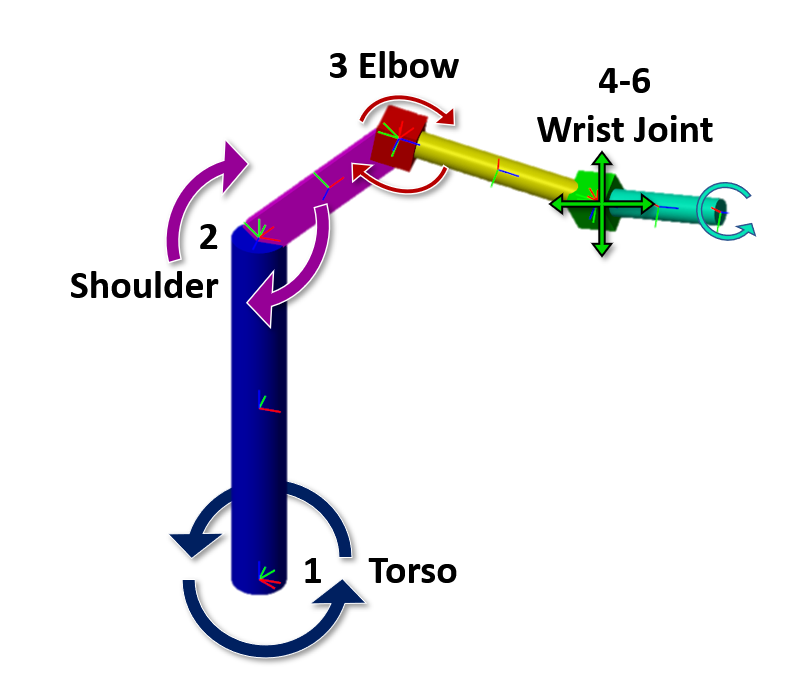

This Robot has:

- A 'Torso' revolute joint (1) for angular rotation (horizontal movement)

- 'Shoulder' (2) and 'Elbow' (3) revolute joints for vertical movement

- A 3 DoF wrist joint (4-6) which can move the end effector to any orientation and rotation within the reachable distance. This is usually accomplished by having 3 revolute joints acting about the same point: 2 for the wrist pitch/yaw motions and 1 for the roll or 'twist' motion.

### Multiple Configurations

The inverse kinematics problem for 6 degrees-of-freedom can become very complex because there are many possible solutions for how to reach a given point. For example, there are 4 possible solutions just for Joints 1-3 for any given point in the workspace. 

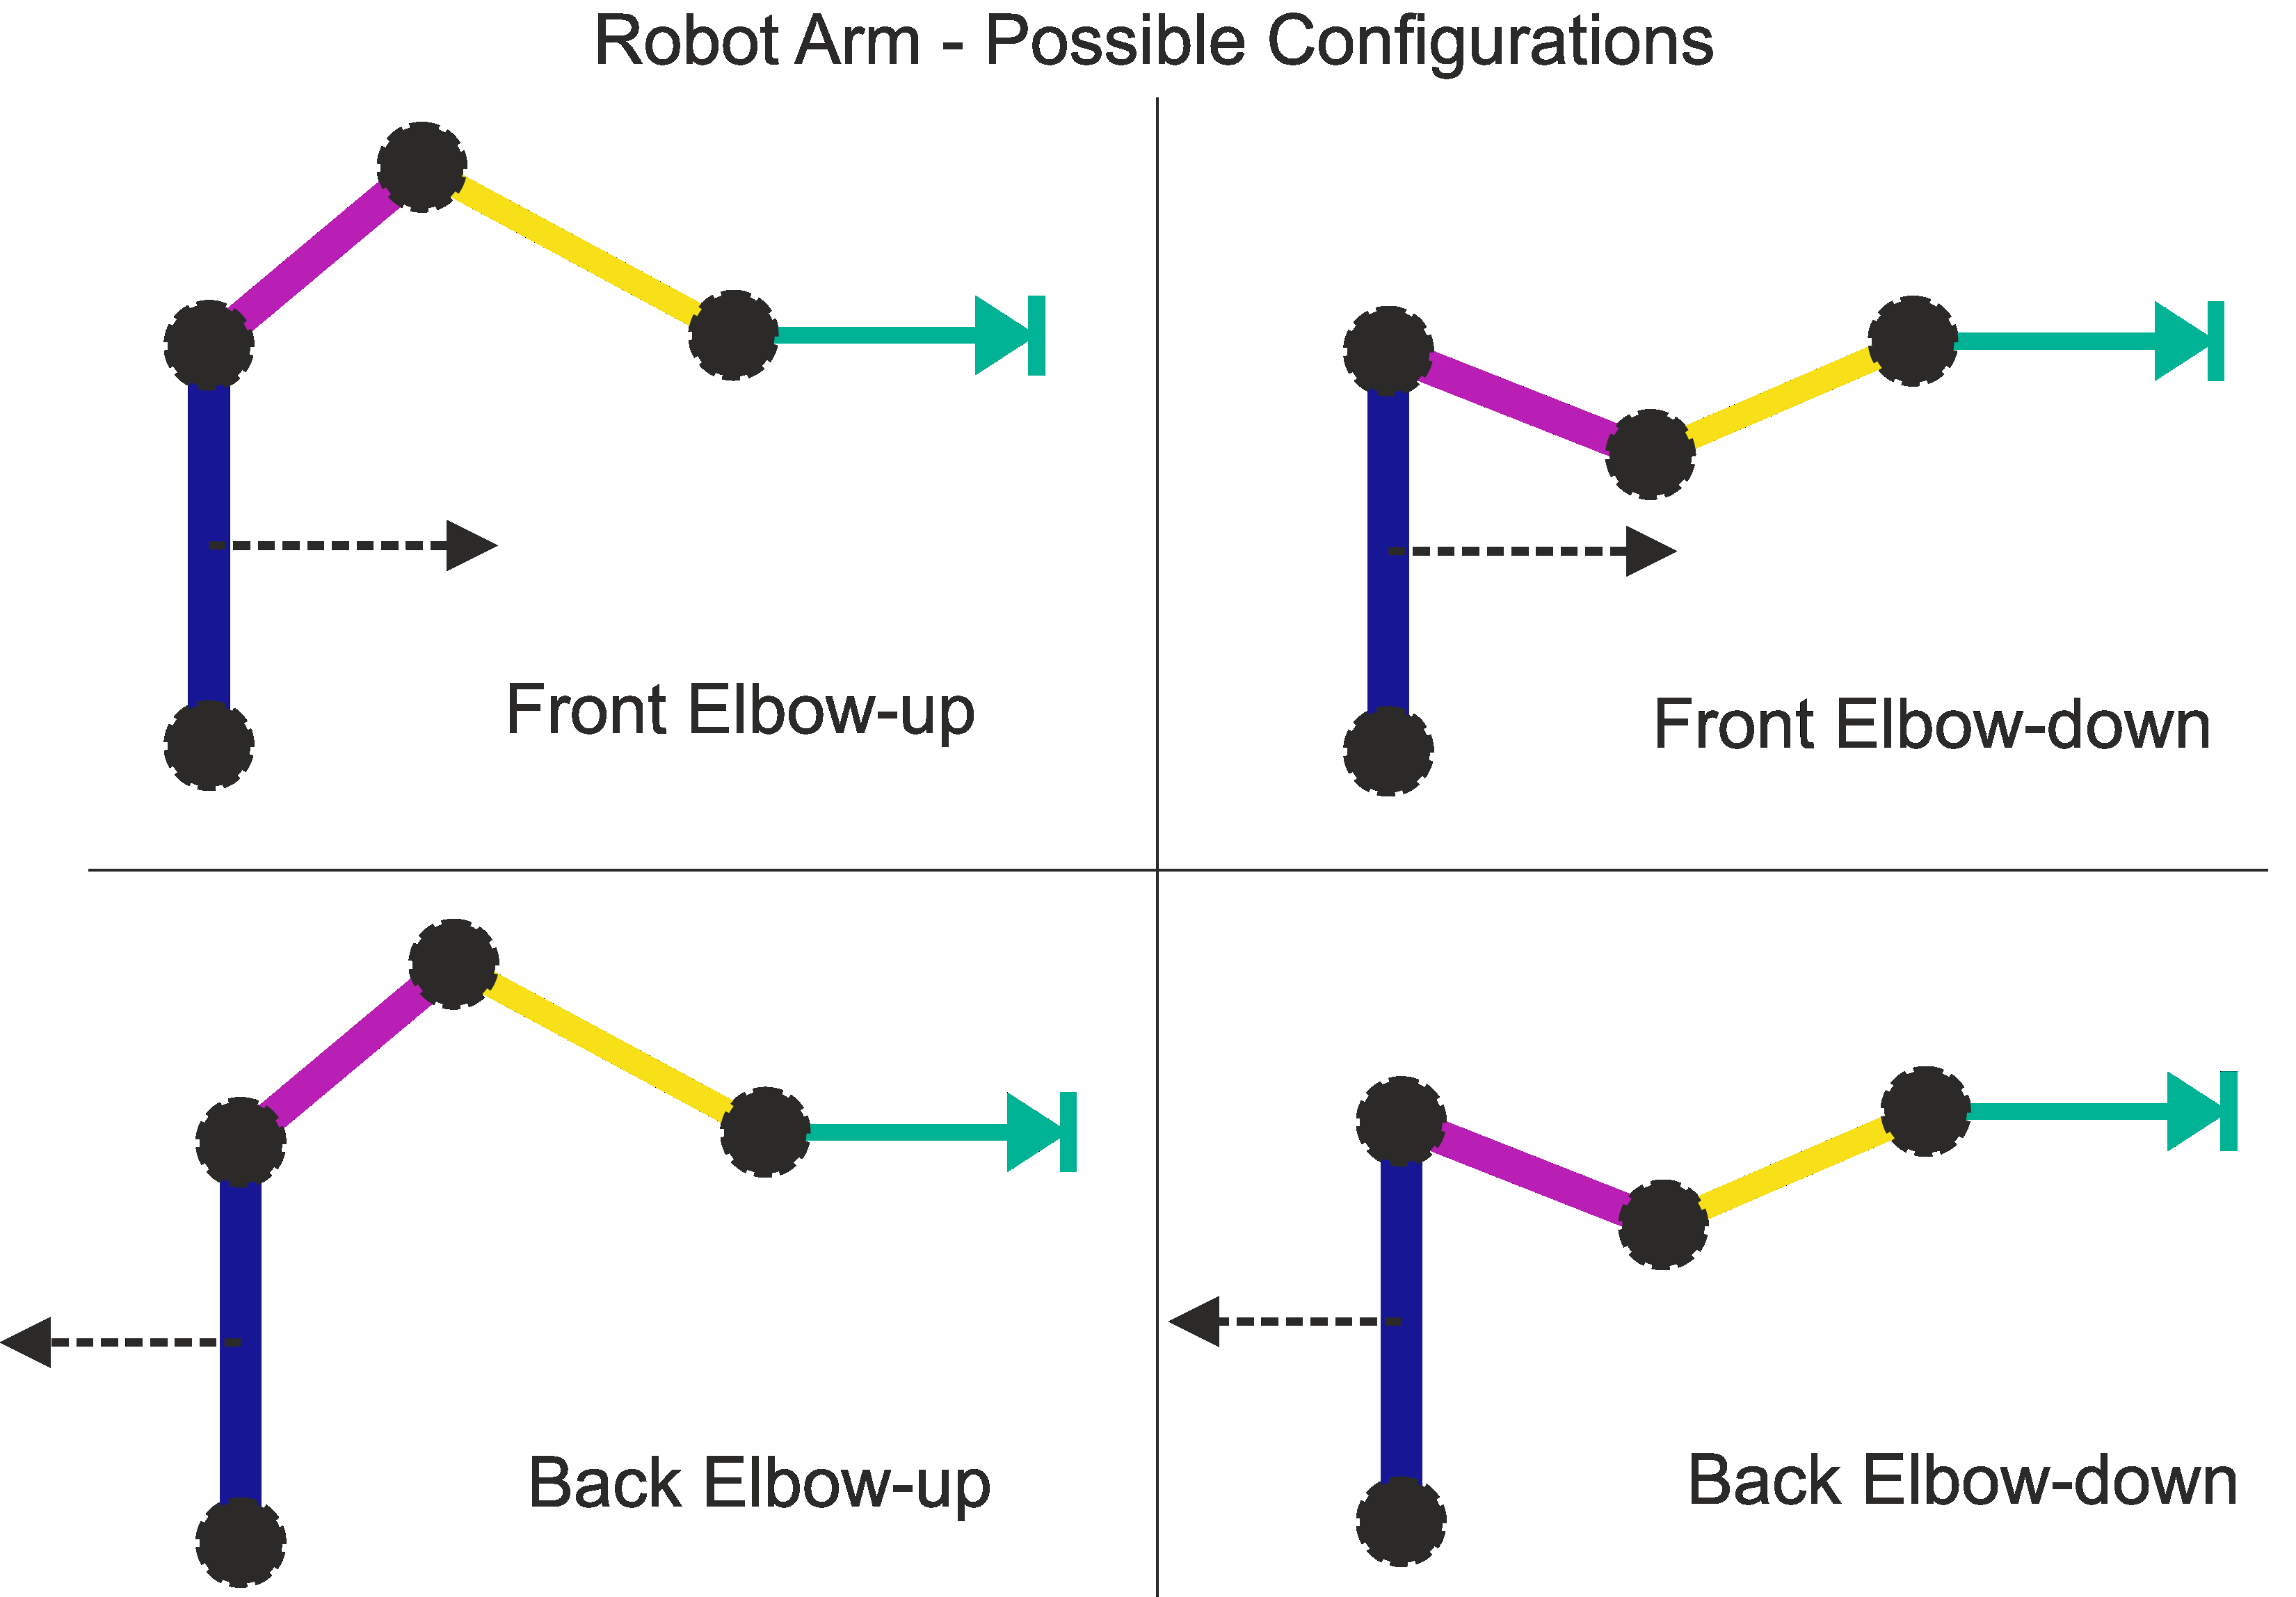

Some solutions can be eliminated using Joint Angle limits, but the problem is still a complex one when 3 more joints are added in at the wrist.

Therefore, in the interest of practicality, we typically break this down into smaller problems. We also must give the following information to solve the inverse kinematics problem, using this approach:

- The (x,y,z) coordinates of the end effector, which is a 3x1 matrix and,

- The Rotation Matrix of the end effector, which defines the orientation from which the tool is approaching the workpiece. This is a 3x3 matrix

- Length of the tool

If the length of the tool and its approach orientation is known, then we can follow the steps described below to calculate the Inverse Kinematics solution for the Joint Angles.

### a. Calculation of Wrist Joint

*Calculate the position (x,y,z) of the wrist joint by working backwards from supplied Translational and Rotational matrices, using the known length of the tool.*  

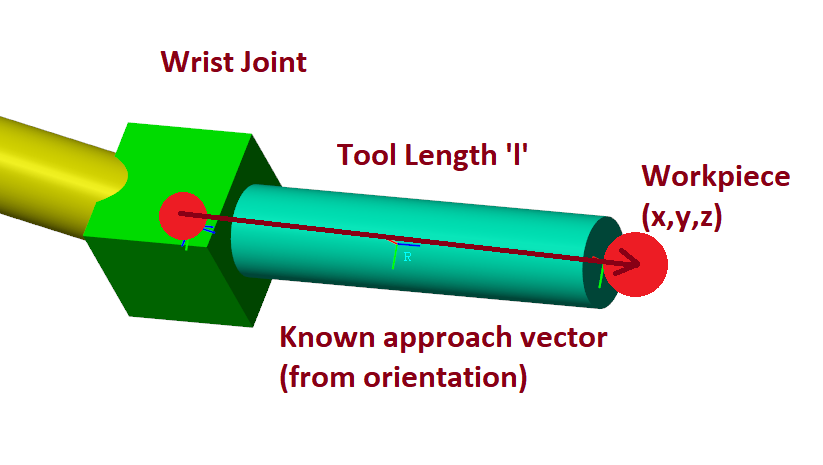

If the position of the workpiece (x,y,z) is known, and the approach vector is known (derived from the supplied matrix 'R'), then calculating the position of the wrist joint is relatively straightforward. 

For example:

% x,y,z coordinates of end-point
p = [0.5 0.5 1] 

p =     0.5000    0.5000    1.0000



% approach vector (in global coordinate frame)
R = [ 0.8365 -0.4830 0.2588;...
      0.4250  0.8700 0.2500;...
     -0.3459 -0.0991 0.9330] 

R =     0.8365   -0.4830    0.2588
    0.4250    0.8700    0.2500
   -0.3459   -0.0991    0.9330



% length of tool in meters
l = 0.1 

l = 0.1000


% z is the direction of axis Z of frame 6 w.r.t base frame
z = [R(1,1) R(2,2) R(3,3)]

z =     0.8365    0.8700    0.9330



%finding wrist center from given end effector position and z6
xc = p(1) - l*z(1);
yc = p(2) - l*z(2);
zc = p(3) - l*z(3);

% wrist center
wc = [xc yc zc]

wc =     0.4163    0.4130    0.9067


### **b. Calculation of Joint Angle 1**

Now we can find out joint angle Theta1 easily by calculating the required rotation. 

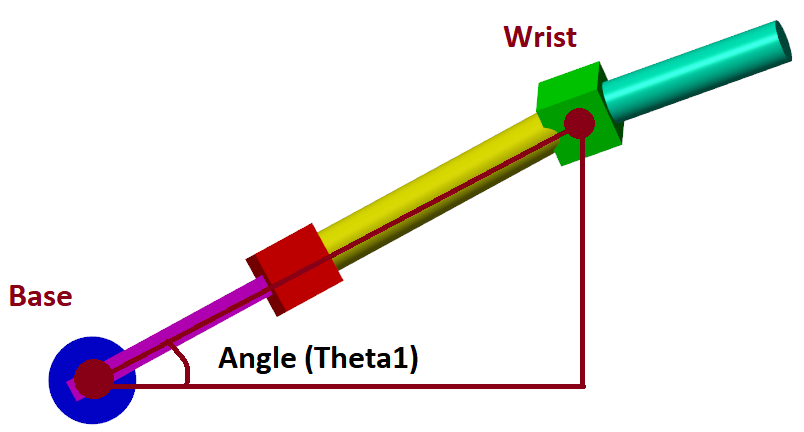

theta1 = rad2deg(atan2(xc,yc))         % degrees

theta1 = 45.2314

Another solution for the 'reverse' or 'backward-bending' position is also possible. For this example, we will consider only the 'forward-facing' solutions, but the reverse angles are also valid solutions and important for many industrial applications.

theta1_alt = rad2deg(atan2(xc,yc))-180 % degrees

theta1_alt = -134.7686

### c. Calculation of Joint Angles 2 & 3

Then, calculating joint angles '2' & '3' is reduced to a much simpler 2DoF problem, as shown below.

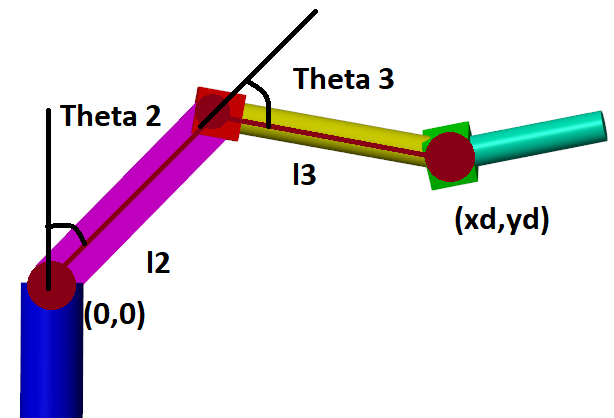

Suppose we are solving for Theta2 and Theta3. Then:

% from above
xd = sqrt(xc^2 + yc^2)

xd = 0.5864

yd = zc- 0.5  % height of first link

yd = 0.4067

l2 = 1        % length l2 (m)

l2 = 1

l3 = 0.75     % l3 (m)

l3 = 0.7500


% distance between base and wrist
d = sqrt(xd^2 + yd^2)

d = 0.7137


% Calculate the forearm link angle
cosb = (l2^2 + l3^2 - d^2)/(2*l2*l3);
sinb = sqrt(1 - cosb.^2);
b = rad2deg(atan2(sinb, cosb))

b = 45.4027

theta3 = 180-b

theta3 = 134.5973


% Calculate the bicep link angle
b1 = rad2deg(atan(yd/xd));
b2 = rad2deg(atan2( (l3*sind(theta3)), (l2+l3*cosd(theta3))));
theta2 = 90-b1-b2

theta2 = 6.8144

Robotics can be confusing with different angle and joint conventions. So it's best to quickly check the calculations once.

x_error = l2*sind(theta2) + l3*sind(theta2+theta3) - xd

x_error = 0

y_error = l2*cosd(theta2) + l3*cosd(theta2+theta3) - yd

y_error = 0

Perfect!

But remember, even here, there are two possible solutions - 'Elbow Up' and 'Elbow Down.' We can select either, depending on the configuration of the robot.

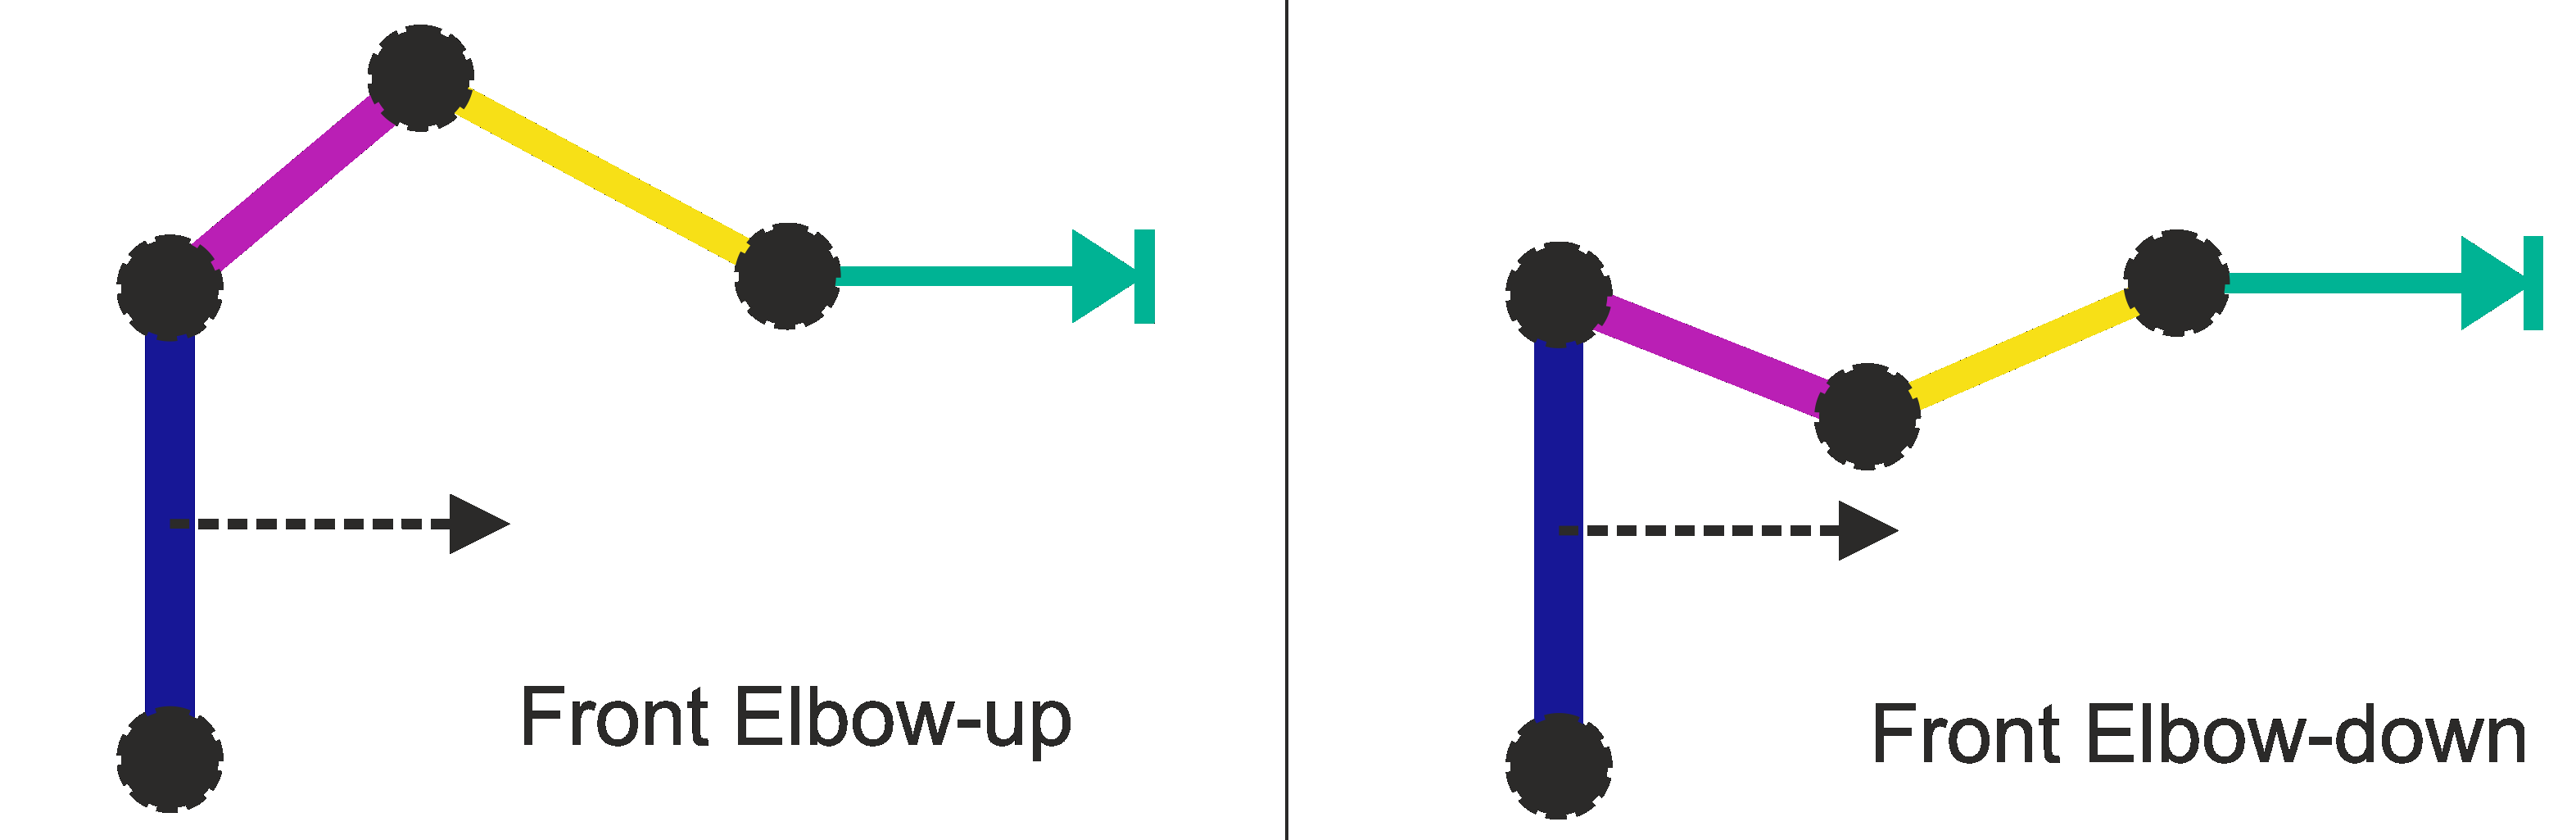

% elbow down solution
theta3_alt = -theta3

theta3_alt = -134.5973

b1 = rad2deg(atan(yd/xd));
b2 = rad2deg(atan2( (l3*sind(theta3_alt)), (l2+l3*cosd(theta3_alt))));
theta2_alt = 90-b1-b2

theta2_alt = 103.7028


x_error = l2*sind(theta2_alt) + l3*sind(theta2_alt+theta3_alt) - xd

x_error = 0

y_error = l2*cosd(theta2_alt) + l3*cosd(theta2_alt+theta3_alt) - yd

y_error = -1.6653e-16

And we can see, that works as well.

### d. Work out the last 3 joint angles

Despite the apparent complexity of the wrist joint, this is actually the easiest step. We need not do this here in detail, but here are the general steps: 

- Once Theta1, Theta2 and Theta3 have been calculated, use the Forward Kinematics to work out $R_3^0$

- As $R_6^0 =R_3^0 R_6^3$, we can use this to calculate the wrist position $R_6^3$ as $R_6^3 ={\left(R_3^0 \right)}^{-1} R_6^0$

- Now simply use Euler Angles to find the last 3 joint values to satisfy$R_6^3$

As we saw in the first script about Rotation Matrices,

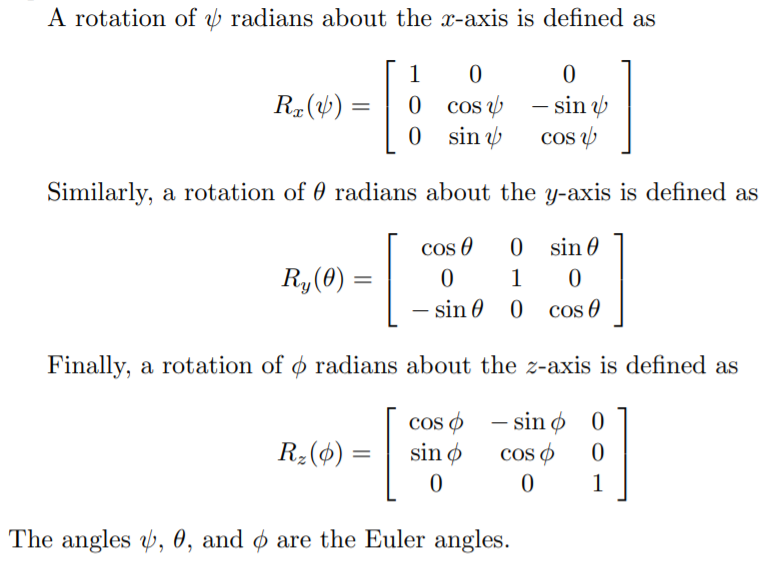

Therefore,

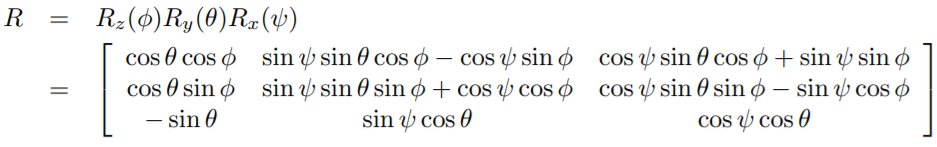

We can solve backwards from this systematically to determine the values of $\theta ,\phi \;$and $\psi$.

How?

If you notice, $R_{3,1} \;=\;-\sin \left(\theta \right)$

Therefore, we can get 2 values of $\theta$ from here.

Similarly, we can use the other parts of the matrix to generate solutions for $\phi \;$and $\psi$.

For example, suppose: 

R = [0.3536 -0.6124  0.7071;...
     0.9268  0.1268 -0.3536;...
    -0.1268  0.7803  0.6124]

R =     0.3536   -0.6124    0.7071
    0.9268    0.1268   -0.3536
   -0.1268    0.7803    0.6124



theta1 = rad2deg(-asin(R(3,1)))

theta1 = 7.2847

theta2 = 180-theta1

theta2 = 172.7153

And so on...

Note that there are always multiple possible solutions for these angles. Therefore the physical limits on the Robot can be used to discard the unrealistic solutions and keep only the workable joint angles.

## 2. Jacobian Inverse Method for a 6DOF Robot

For the Jacobian Inverse, we will require the end location of the end-effector and the transformation matrices calculated from the forward kinematics. Recall that the transformation matrix comprises the rotation (3x3) and translation (3x1) matrices.

The Jacobian Inverse Method is the most widely used iterative technique in solving inverse kinematic problems. The first step is to compute the Jacobian matrix as a function of the transformation matrices (specifically, the joint angles) and then take its inverse. Then, we can iterate on the end-effector's current location until its target location is achieved. As this happens, the joint angles will change slowly to move the robot arm to its final location within some tolerance. This means that with new joint angles, we will have to calculate new forward kinematics (new transformation matrices) for the next location achieved by the end-effector. The Jacobian also depends on the forward kinematics and will change every iteration. 

### a. The Jacobian Matrix

In robotics, the Jacobian matrix ($J$) provides a direct correlation between the joint velocities ($\dot
X$) and the end-effector velocities ($\dot
q$):

#### 
$$\dot
X = J \dot
q$$


Therefore, the inverse Jacobian matrix satisfies the equation:

#### 
$$\dot
q = J^{-1}
\dot  X$$


Since we are dealing with joint angles instead of joint velocities, we require an expression that correlates the  joint positions ($\delta
q$) and end-effector displacement ($\delta  X$) instead:

#### 
$$\delta
q = J^{-1}
\delta  X$$


Where $\delta$ represents an incremental change in the end-effector position and joint angles. The number of rows in a Jacobian matrix depends on the type of robot and its DOF. Since we mentioned earlier that the robot is **spatial** and **fully actuated**, it will have 6DOF or six rows. The number of columns in a Jacobian matrix depends on the robot's number of joints. Therefore, the matrix will also have six columns, also known as a square matrix:

#### 
$$\left\lbrack \begin{array}{c}
{\delta q}_1 \\
{\delta q}_2 \\
{\delta q}_3 \\
{\delta q}_4 \\
{\delta q}_5 \\
{\delta q}_6 
\end{array}\right\rbrack ={\left\lbrack \begin{array}{cccccc}
J_{11}  & J_{12}  & J_{13}  & J_{14}  & J_{15}  & J_{16} \\
J_{21}  & J_{22}  & J_{23}  & J_{24}  & J_{25}  & J_{26} \\
J_{31}  & J_{32}  & J_{33}  & J_{34}  & J_{35}  & J_{36} \\
J_{41}  & J_{42}  & J_{43}  & J_{44}  & J_{45}  & J_{46} \\
J_{51}  & J_{52}  & J_{53}  & J_{54}  & J_{55}  & J_{56} \\
J_{61}  & J_{62}  & J_{63}  & J_{64}  & J_{65}  & J_{66} 
\end{array}\right\rbrack }^{-1} \cdot \left\lbrack \begin{array}{c}
\delta x\\
\delta y\\
\delta z\\
\delta \alpha \\
\delta \beta \\
\delta \gamma 
\end{array}\right\rbrack$$


Where:

-  $q_1 -q_6$ represents the incremental joint position changes and,

-  $x,y,z$ and $\alpha ,\beta ,\gamma$ represent the end-effector's linear position and rotational orientation, respectively. 

**Note:** For under-actuated and redundant robots, the Jacobian matrix will always be non-square. That means the number of joints in the robot does not equal the number of DOFs.

### b. Defining the Jacobian Matrix

The vector $\delta X$ is split into two parts (linear and rotational) representing the end-effector's movement. The same is true for the Jacobian matrix:

            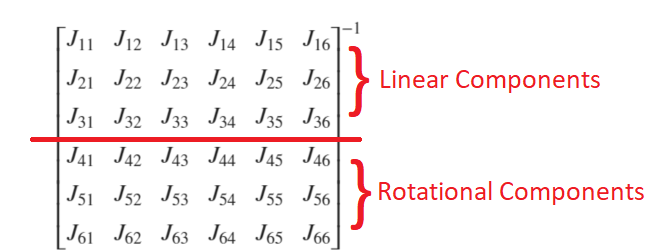

To find the linear and rotational elements of the Jacobian, we can use the following guide:

**   For Prismatic Joints**                                   **For Revolute Joints**

              Linear: $R_{i-1}^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$                                    Linear: $R_{i-1}^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \times \left(d_n^0 -d_{i-1}^0 \right)$

Rotational: $\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack$                                     Rotational: $R_{i-1}^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$

Where $i$ is the joint of interest and $n$ is the total number of joints in the robot. Observe the 3x1 vector multiplied by the rotational matrix in the prismatic or revolute case. This vector defines the joint's normal vector (or axis of rotation). This guide was written based on the assumption that each joint will rotate along the z-axis, hence the value of 1 in the 3rd position of the vector. It is essential to understand that this vector will vary based on the rotation of your joints. 

Let's define the inverse Jacobian matrix for a spatial fully actuated robot (6DOF) with all revolute joints (and rotation of joints focused around the z-axis). Using the sample inverse Jacobian matrix above, we have the following 6x6 matrix:

#### 
$${\left\lbrack \begin{array}{cccccc}
J_{11}  & J_{12}  & J_{13}  & J_{14}  & J_{15}  & J_{16} \\
J_{21}  & J_{22}  & J_{23}  & J_{24}  & J_{25}  & J_{26} \\
J_{31}  & J_{32}  & J_{33}  & J_{34}  & J_{35}  & J_{36} \\
J_{41}  & J_{42}  & J_{43}  & J_{44}  & J_{45}  & J_{46} \\
J_{51}  & J_{52}  & J_{53}  & J_{54}  & J_{55}  & J_{56} \\
J_{61}  & J_{62}  & J_{63}  & J_{64}  & J_{65}  & J_{66} 
\end{array}\right\rbrack }^{-1} \Longrightarrow {\left\lbrack \begin{array}{cccccc}
R_0^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \times \left(d_6^0 -d_0^0 \right) & R_1^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \times \left(d_6^0 -d_1^0 \right) & R_2^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \times \left(d_6^0 -d_2^0 \right) & R_3^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \times \left(d_6^0 -d_3^0 \right) & R_4^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \times \left(d_6^0 -d_4^0 \right) & R_5^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \times \left(d_6^0 -d_5^0 \right)\\
R_0^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack  & R_1^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack  & R_2^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack  & R_3^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack  & R_4^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack  & R_5^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack 
\end{array}\right\rbrack }^{-1}$$


Observe the notation, $R_0^0$. This would represent the rotation from frame zero to itself. There is no rotation between the same frame; therefore, $R_0^0$ is expressed as the identity matrix. In addition, the displacement from the center of a frame to itself is also zero, therefore $d_0^0 =0$. The other components can be found from the transformation matrices found doing the forward kinematics of the robot. Meaning $R_{i-1}^0$, $d_n^0$, and $d_{i-1}^0$ can be found from $T_{i-1}^0$:

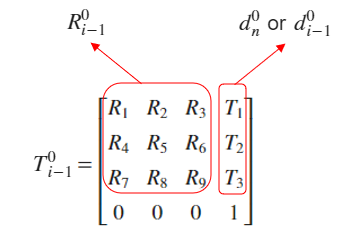

Rather than finding these components individually, there is a shortcut approach to finding the product of the rotation matrix $R_{i-1}^0$ (3x3) and the axis of rotation vector $\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$ (3x1). Using the coordinate frames of the joints to determine the axis of rotation, we can pull the resulting vector (3x1) of that product directly from the corresponding transformation matrix. For instance, if a joint is rotating about the Y-axis, the product of the rotation matrix and the axis of rotation vector is the second column of the transformation matrix:

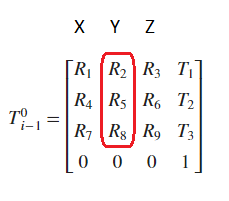

**Note: **The DH parameters described and used in this script are based on the **standard convention**, not modified. 

That's it for Inverse Kinematics for single points. The next step is to generate trajectories of motion for moving paths. The [next example](matlab:open('./IK02-TwoJointInverseKinematics.mlx')) shows how to do this using built-in functions for a simple 2-link robot.